%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Simple example for comparison and evaluation of BOP-DMD
%
% Here we fit data generated from 3 
% spatial modes, each with time dynamics 
% which are exponential in time. 
%
% This example is used to compare between this reference code
% and the python version of this code.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% ToDo:
% Loop of sigma
% Scatter plots of eigenvalues
% Alignment using match_vectors

clear all, close all, clc

## generate synthetic data

% set up modes in space

x0 = 0;
x1 = 1;
nx = 200;

% space

xspace = linspace(x0,x1,nx);

% modes

f1 = sin(xspace);
f2 = cos(xspace);
f3 = tanh(xspace);

% set up time dynamics

t0 = 0;
t1 = 1;
nt = 100;

ts = linspace(t0,t1,nt);

% eigenvalues

e_1 = 1;
e_2 = -2;
e_3 = 1i;

true_eigenvalues = [e_1;e_2;e_3];

% create clean dynamics

xclean = f1'*exp(e_1*ts) + f2'*exp(e_2*ts) + f3'*exp(e_3*ts);

## Run the BOP-DMD for varying levels of noise (sigma)

% Turn off the rank deficient warning as this triggers constantly
% for the higher levels of noise.
warning('off', 'MATLAB:rankDeficientMatrix')

% Set an array of varying levels of noise.
sigma_array = [0.1];

% Determine the number of points along the time dimension.
n = length(ts);

% Set the number of samples to use for each ensemble member.
p = 50;

% Determine the number of realizations of the noisy data.
num_Noisecycles = 5;

% Determine the number of ensemble members for each BOP-DMD solution.
num_cycles =  10;

% Initialize the matrices of eigenvalue solutions...

% ... for optDMD
lambda_vec_optDMD = zeros(3, num_Noisecycles, length(sigma_array));

% ... for BOP-DMD
lambda_vec_ensembleDMD = zeros(3, num_Noisecycles * num_cycles, length(sigma_array));

% Initialize the random seed
rand(1);

for sigma_ind = 1:length(sigma_array)
    fprintf('Sigma=%f\n', sigma_array(sigma_ind))
    for k = 1: num_Noisecycles
        fprintf('Realization %i of %i \n', k, num_Noisecycles)

        % Create data for this realization of noisy data.
        xdata = xclean + sigma_array(sigma_ind) * randn(size(xclean));

        % Run the optdmd.
        [w_opt,e_opt,b_opt] = optdmd(xdata,ts,3,1,varpro_opts('ifprint',0));
        
        % Compare to actual eigenvalues
        indices = match_vectors(e_opt, true_eigenvalues);
        lambda_vec_optDMD(:, k, sigma_ind) = e_opt(indices);
        
        for j = 1:num_cycles
                fprintf('Ensemble %i of %i \n', j, num_cycles)
                % Generate the ensemble members.
                unsorted_ind = randperm(n,p);
                % Sort to be in ascending order. NOTE that we now have a
                % variable delta t between members.
                ind = sort(unsorted_ind);
        
                % Create dataset for this cycle using the ensemble indices.
                xdata_cycle = xdata(:,ind);
                % Provide the index times.
                ts_ind = ts(ind);
        
                % Run the BOP-DMD with the optDMD modes as the initial conditions.
                [w_cycle,e_cycle,b_cycle] = optdmd(xdata_cycle,ts_ind,3,1,varpro_opts('ifprint',0),e_opt);

                % compare to actual eigenvalues
                indices = match_vectors(e_cycle, true_eigenvalues);
                relerr_e = norm(e_cycle(indices)-true_eigenvalues)/norm(true_eigenvalues);
                
                if relerr_e > 1
                    fprintf('Eigenvalue error = %e\nBecoming verbose',relerr_e)
                    % Re-run the BOP-DMD in verbose mode.
                    [w_cycle,e_cycle,b_cycle] = optdmd(xdata_cycle,ts_ind,3,1,varpro_opts('ifprint',1),e_opt);

                end

                % Compare to actual eigenvalues.
                indices = match_vectors(e_cycle, true_eigenvalues);
                lambda_vec_ensembleDMD(:, j * k, sigma_ind) = e_cycle(indices);

        end
    end
end

Sigma=0.100000


Realization 1 of 5 


Ensemble 1 of 10 


Error eigenvalues 1.770396e+00
Becoming verbose

step 1 err 4.718840e+01 lambda 3.333333e-01
step 2 err 4.718634e+01 lambda 1.111111e-01
step 3 err 4.718443e+01 lambda 3.703704e-02
step 4 err 4.718252e+01 lambda 1.234568e-02
step 5 err 4.718065e+01 lambda 4.115226e-03
step 6 err 4.717883e+01 lambda 1.371742e-03
step 7 err 4.717707e+01 lambda 4.572474e-04
step 8 err 4.717538e+01 lambda 1.524158e-04
step 9 err 4.717377e+01 lambda 5.080526e-05
step 10 err 4.717225e+01 lambda 1.693509e-05
step 11 err 4.717081e+01 lambda 5.645029e-06
step 12 err 4.716947e+01 lambda 1.881676e-06
step 13 err 4.716822e+01 lambda 6.272255e-07
step 14 err 4.716708e+01 lambda 2.090752e-07
step 15 err 4.716602e+01 lambda 6.969172e-08
step 16 err 4.716505e+01 lambda 2.323057e-08
step 17 err 4.716417e+01 lambda 7.743524e-09
step 18 err 4.716338e+01 lambda 2.581175e-09
step 19 err 4.716265e+01 lambda 8.603916e-10
step 20 err 4.716200e+01 lambda 2.867972e-10
step 21 err 4.716141e+01 lambda 9.559907e-11
step 22 err 4.716088e+01 lambda 3.186636e-11
step 23 err 4.71604

Ensemble 2 of 10 


Error eigenvalues 3.874752e+00
Becoming verbose

step 1 err 4.714561e+01 lambda 3.333333e-01
step 2 err 4.712871e+01 lambda 1.111111e-01
step 3 err 4.711198e+01 lambda 3.703704e-02
step 4 err 4.709671e+01 lambda 1.234568e-02
step 5 err 4.708311e+01 lambda 4.115226e-03
step 6 err 4.707121e+01 lambda 1.371742e-03
step 7 err 4.706095e+01 lambda 4.572474e-04
step 8 err 4.705225e+01 lambda 1.524158e-04
step 9 err 4.704495e+01 lambda 5.080526e-05
step 10 err 4.703890e+01 lambda 1.693509e-05
step 11 err 4.703391e+01 lambda 5.645029e-06
step 12 err 4.702983e+01 lambda 1.881676e-06
step 13 err 4.702650e+01 lambda 6.272255e-07
step 14 err 4.702379e+01 lambda 2.090752e-07
step 15 err 4.702159e+01 lambda 6.969172e-08
step 16 err 4.701980e+01 lambda 2.323057e-08
step 17 err 4.701834e+01 lambda 7.743524e-09
step 18 err 4.701715e+01 lambda 2.581175e-09
step 19 err 4.701618e+01 lambda 8.603916e-10
step 20 err 4.701539e+01 lambda 2.867972e-10
step 21 err 4.701475e+01 lambda 9.559907e-11
step 22 err 4.701422e+01 lambda 3.186636e-11
step 23 err 4.70137

Ensemble 3 of 10 
Ensemble 4 of 10 


Error eigenvalues 1.864816e+00
Becoming verbose

step 1 err 4.696729e+01 lambda 3.333333e-01
step 2 err 4.696671e+01 lambda 1.111111e-01
step 3 err 4.696629e+01 lambda 3.703704e-02
step 4 err 4.696591e+01 lambda 1.234568e-02
step 5 err 4.696556e+01 lambda 4.115226e-03
step 6 err 4.696526e+01 lambda 1.371742e-03
step 7 err 4.696498e+01 lambda 4.572474e-04
step 8 err 4.696473e+01 lambda 1.524158e-04
step 9 err 4.696451e+01 lambda 5.080526e-05
step 10 err 4.696430e+01 lambda 1.693509e-05
step 11 err 4.696412e+01 lambda 5.645029e-06
step 12 err 4.696395e+01 lambda 1.881676e-06
step 13 err 4.696379e+01 lambda 6.272255e-07
step 14 err 4.696365e+01 lambda 2.090752e-07
step 15 err 4.696353e+01 lambda 6.969172e-08
step 16 err 4.696341e+01 lambda 2.323057e-08
step 17 err 4.696330e+01 lambda 7.743524e-09
step 18 err 4.696320e+01 lambda 2.581175e-09
step 19 err 4.696311e+01 lambda 8.603916e-10
step 20 err 4.696302e+01 lambda 2.867972e-10
step 21 err 4.696294e+01 lambda 9.559907e-11
step 22 err 4.696287e+01 lambda 3.186636e-11
step 23 err 4.69628

Ensemble 5 of 10 


Error eigenvalues 3.346210e+00
Becoming verbose

step 1 err 4.763563e+01 lambda 3.333333e-01
step 2 err 4.763192e+01 lambda 1.111111e-01
step 3 err 4.762825e+01 lambda 3.703704e-02
step 4 err 4.762478e+01 lambda 1.234568e-02
step 5 err 4.762157e+01 lambda 4.115226e-03
step 6 err 4.761864e+01 lambda 1.371742e-03
step 7 err 4.761597e+01 lambda 4.572474e-04
step 8 err 4.761356e+01 lambda 1.524158e-04
step 9 err 4.761139e+01 lambda 5.080526e-05
step 10 err 4.760945e+01 lambda 1.693509e-05
step 11 err 4.760772e+01 lambda 5.645029e-06
step 12 err 4.760617e+01 lambda 1.881676e-06
step 13 err 4.760478e+01 lambda 6.272255e-07
step 14 err 4.760355e+01 lambda 2.090752e-07
step 15 err 4.760244e+01 lambda 6.969172e-08
step 16 err 4.760144e+01 lambda 2.323057e-08
step 17 err 4.760055e+01 lambda 7.743524e-09
step 18 err 4.759974e+01 lambda 2.581175e-09
step 19 err 4.759901e+01 lambda 8.603916e-10
step 20 err 4.759834e+01 lambda 2.867972e-10
step 21 err 4.759773e+01 lambda 9.559907e-11
step 22 err 4.759718e+01 lambda 3.186636e-11
step 23 err 4.75966

Ensemble 6 of 10 


Error eigenvalues 3.391158e+00
Becoming verbose

step 1 err 4.713948e+01 lambda 3.333333e-01
step 2 err 4.712443e+01 lambda 1.111111e-01
step 3 err 4.711233e+01 lambda 3.703704e-02
step 4 err 4.710396e+01 lambda 1.234568e-02
step 5 err 4.709857e+01 lambda 4.115226e-03
step 6 err 4.709523e+01 lambda 1.371742e-03
step 7 err 4.709320e+01 lambda 4.572474e-04
step 8 err 4.709198e+01 lambda 1.524158e-04
step 9 err 4.709124e+01 lambda 5.080526e-05
step 10 err 4.709079e+01 lambda 1.693509e-05
step 11 err 4.709052e+01 lambda 5.645029e-06
step 12 err 4.709035e+01 lambda 1.881676e-06
step 13 err 4.709023e+01 lambda 6.272255e-07
step 14 err 4.709016e+01 lambda 2.090752e-07
step 15 err 4.709010e+01 lambda 6.969172e-08
step 16 err 4.709006e+01 lambda 2.323057e-08
step 17 err 4.709003e+01 lambda 7.743524e-09
step 18 err 4.709001e+01 lambda 2.581175e-09
step 19 err 4.708998e+01 lambda 8.603916e-10
step 20 err 4.708996e+01 lambda 2.867972e-10
step 21 err 4.708995e+01 lambda 9.559907e-11
step 22 err 4.708993e+01 lambda 3.186636e-11
step 23 err 4.70899

Ensemble 7 of 10 


Error eigenvalues 3.838023e+00
Becoming verbose

step 1 err 4.641100e+01 lambda 3.333333e-01
step 2 err 4.639764e+01 lambda 1.111111e-01
step 3 err 4.638611e+01 lambda 3.703704e-02
step 4 err 4.637629e+01 lambda 1.234568e-02
step 5 err 4.636827e+01 lambda 4.115226e-03
step 6 err 4.636189e+01 lambda 1.371742e-03
step 7 err 4.635690e+01 lambda 4.572474e-04
step 8 err 4.635307e+01 lambda 1.524158e-04
step 9 err 4.635014e+01 lambda 5.080526e-05
step 10 err 4.634792e+01 lambda 1.693509e-05
step 11 err 4.634625e+01 lambda 5.645029e-06
step 12 err 4.634500e+01 lambda 1.881676e-06
step 13 err 4.634405e+01 lambda 6.272255e-07
step 14 err 4.634335e+01 lambda 2.090752e-07
step 15 err 4.634282e+01 lambda 6.969172e-08
step 16 err 4.634242e+01 lambda 2.323057e-08
step 17 err 4.634212e+01 lambda 7.743524e-09
step 18 err 4.634189e+01 lambda 2.581175e-09
step 19 err 4.634172e+01 lambda 8.603916e-10
step 20 err 4.634159e+01 lambda 2.867972e-10
step 21 err 4.634150e+01 lambda 9.559907e-11
step 22 err 4.634143e+01 lambda 3.186636e-11
step 23 err 4.63413

Ensemble 8 of 10 


Error eigenvalues 4.493075e+00
Becoming verbose

step 1 err 4.777936e+01 lambda 3.333333e-01
step 2 err 4.777199e+01 lambda 1.111111e-01
step 3 err 4.776482e+01 lambda 3.703704e-02
step 4 err 4.775817e+01 lambda 1.234568e-02
step 5 err 4.775214e+01 lambda 4.115226e-03
step 6 err 4.774679e+01 lambda 1.371742e-03
step 7 err 4.774211e+01 lambda 4.572474e-04
step 8 err 4.773806e+01 lambda 1.524158e-04
step 9 err 4.773460e+01 lambda 5.080526e-05
step 10 err 4.773167e+01 lambda 1.693509e-05
step 11 err 4.772920e+01 lambda 5.645029e-06
step 12 err 4.772712e+01 lambda 1.881676e-06
step 13 err 4.772539e+01 lambda 6.272255e-07
step 14 err 4.772393e+01 lambda 2.090752e-07
step 15 err 4.772272e+01 lambda 6.969172e-08
step 16 err 4.772169e+01 lambda 2.323057e-08
step 17 err 4.772083e+01 lambda 7.743524e-09
step 18 err 4.772011e+01 lambda 2.581175e-09
step 19 err 4.771949e+01 lambda 8.603916e-10
step 20 err 4.771897e+01 lambda 2.867972e-10
step 21 err 4.771852e+01 lambda 9.559907e-11
step 22 err 4.771814e+01 lambda 3.186636e-11
step 23 err 4.77178

Ensemble 9 of 10 


Error eigenvalues 2.584552e+00
Becoming verbose

step 1 err 4.706234e+01 lambda 3.333333e-01
step 2 err 4.706206e+01 lambda 1.111111e-01
step 3 err 4.706196e+01 lambda 3.703704e-02
step 4 err 4.706187e+01 lambda 1.234568e-02
step 5 err 4.706179e+01 lambda 4.115226e-03
step 6 err 4.706172e+01 lambda 1.371742e-03
step 7 err 4.706166e+01 lambda 4.572474e-04
step 8 err 4.706160e+01 lambda 1.524158e-04
step 9 err 4.706155e+01 lambda 5.080526e-05
step 10 err 4.706150e+01 lambda 1.693509e-05
step 11 err 4.706145e+01 lambda 5.645029e-06
step 12 err 4.706141e+01 lambda 1.881676e-06
step 13 err 4.706136e+01 lambda 6.272255e-07
step 14 err 4.706132e+01 lambda 2.090752e-07
step 15 err 4.706129e+01 lambda 6.969172e-08
step 16 err 4.706125e+01 lambda 2.323057e-08
step 17 err 4.706121e+01 lambda 7.743524e-09
step 18 err 4.706118e+01 lambda 2.581175e-09
step 19 err 4.706115e+01 lambda 8.603916e-10
step 20 err 4.706111e+01 lambda 2.867972e-10
step 21 err 4.706108e+01 lambda 9.559907e-11
step 22 err 4.706105e+01 lambda 3.186636e-11
step 23 err 4.70610

Ensemble 10 of 10 


Error eigenvalues 2.801164e+00
Becoming verbose

step 1 err 4.623276e+01 lambda 3.333333e-01
step 2 err 4.623240e+01 lambda 1.111111e-01
step 3 err 4.623229e+01 lambda 3.703704e-02
step 4 err 4.623217e+01 lambda 1.234568e-02
step 5 err 4.623206e+01 lambda 4.115226e-03
step 6 err 4.623195e+01 lambda 1.371742e-03
step 7 err 4.623184e+01 lambda 4.572474e-04
step 8 err 4.623173e+01 lambda 1.524158e-04
step 9 err 4.623162e+01 lambda 5.080526e-05
step 10 err 4.623151e+01 lambda 1.693509e-05
step 11 err 4.623140e+01 lambda 5.645029e-06
step 12 err 4.623129e+01 lambda 1.881676e-06
step 13 err 4.623119e+01 lambda 6.272255e-07
step 14 err 4.623108e+01 lambda 2.090752e-07
step 15 err 4.623098e+01 lambda 6.969172e-08
step 16 err 4.623087e+01 lambda 2.323057e-08
step 17 err 4.623077e+01 lambda 7.743524e-09
step 18 err 4.623067e+01 lambda 2.581175e-09
step 19 err 4.623056e+01 lambda 8.603916e-10
step 20 err 4.623046e+01 lambda 2.867972e-10
step 21 err 4.623036e+01 lambda 9.559907e-11
step 22 err 4.623026e+01 lambda 3.186636e-11
step 23 err 4.62301

Realization 2 of 5 


Ensemble 1 of 10 


Error eigenvalues 3.855178e+00
Becoming verbose

step 1 err 4.791097e+01 lambda 3.333333e-01
step 2 err 4.790187e+01 lambda 1.111111e-01
step 3 err 4.789834e+01 lambda 3.703704e-02
step 4 err 4.789730e+01 lambda 3.714976e-02
step 5 err 4.789044e+01 lambda 1.238325e-02
step 6 err 4.788670e+01 lambda 4.127751e-03
step 7 err 4.788291e+01 lambda 1.375917e-03
step 8 err 4.787918e+01 lambda 4.586390e-04
step 9 err 4.787551e+01 lambda 1.528797e-04
step 10 err 4.787191e+01 lambda 5.095988e-05
step 11 err 4.786840e+01 lambda 1.698663e-05
step 12 err 4.786499e+01 lambda 5.662209e-06
step 13 err 4.786167e+01 lambda 1.887403e-06
step 14 err 4.785845e+01 lambda 6.291344e-07
step 15 err 4.785533e+01 lambda 2.097115e-07
step 16 err 4.785234e+01 lambda 6.990382e-08
step 17 err 4.784946e+01 lambda 2.330127e-08
step 18 err 4.784672e+01 lambda 7.767091e-09
step 19 err 4.784411e+01 lambda 2.589030e-09
step 20 err 4.784167e+01 lambda 8.630101e-10
step 21 err 4.783938e+01 lambda 2.876700e-10
step 22 err 4.783726e+01 lambda 9.589001e-11
step 23 err 4.78353

Ensemble 2 of 10 


Error eigenvalues 1.429448e+00
Becoming verbose

step 1 err 4.757756e+01 lambda 3.333333e-01
step 2 err 4.757129e+01 lambda 1.111111e-01
step 3 err 4.757042e+01 lambda 3.703704e-02
step 4 err 4.757031e+01 lambda 1.234568e-02
step 5 err 4.757021e+01 lambda 4.115226e-03
step 6 err 4.757010e+01 lambda 1.371742e-03
step 7 err 4.757000e+01 lambda 4.572474e-04
step 8 err 4.756991e+01 lambda 1.524158e-04
step 9 err 4.756981e+01 lambda 5.080526e-05
step 10 err 4.756972e+01 lambda 1.693509e-05
step 11 err 4.756962e+01 lambda 5.645029e-06
step 12 err 4.756953e+01 lambda 1.881676e-06
step 13 err 4.756944e+01 lambda 6.272255e-07
step 14 err 4.756935e+01 lambda 2.090752e-07
step 15 err 4.756926e+01 lambda 6.969172e-08
step 16 err 4.756917e+01 lambda 2.323057e-08
step 17 err 4.756908e+01 lambda 7.743524e-09
step 18 err 4.756900e+01 lambda 2.581175e-09
step 19 err 4.756891e+01 lambda 8.603916e-10
step 20 err 4.756883e+01 lambda 2.867972e-10
step 21 err 4.756874e+01 lambda 9.559907e-11
step 22 err 4.756866e+01 lambda 3.186636e-11
step 23 err 4.75685

Ensemble 3 of 10 
Ensemble 4 of 10 


Error eigenvalues 1.924324e+00
Becoming verbose

step 1 err 4.795434e+01 lambda 3.333333e-01
step 2 err 4.795136e+01 lambda 1.111111e-01
step 3 err 4.794958e+01 lambda 3.703704e-02
step 4 err 4.794820e+01 lambda 1.234568e-02
step 5 err 4.794675e+01 lambda 4.115226e-03
step 6 err 4.794576e+01 lambda 1.371742e-03
step 7 err 4.794497e+01 lambda 4.572474e-04
step 8 err 4.794432e+01 lambda 1.524158e-04
step 9 err 4.794378e+01 lambda 5.080526e-05
step 10 err 4.794332e+01 lambda 1.693509e-05
step 11 err 4.794292e+01 lambda 5.645029e-06
step 12 err 4.794257e+01 lambda 1.881676e-06
step 13 err 4.794227e+01 lambda 6.272255e-07
step 14 err 4.794199e+01 lambda 2.090752e-07
step 15 err 4.794174e+01 lambda 6.969172e-08
step 16 err 4.794152e+01 lambda 2.323057e-08
step 17 err 4.794132e+01 lambda 7.743524e-09
step 18 err 4.794113e+01 lambda 2.581175e-09
step 19 err 4.794097e+01 lambda 8.603916e-10
step 20 err 4.794081e+01 lambda 2.867972e-10
step 21 err 4.794068e+01 lambda 9.559907e-11
step 22 err 4.794055e+01 lambda 3.186636e-11
step 23 err 4.79404

Ensemble 5 of 10 


Error eigenvalues 5.047219e+00
Becoming verbose

step 1 err 4.710007e+01 lambda 3.333333e-01
step 2 err 4.709480e+01 lambda 1.111111e-01
step 3 err 4.709356e+01 lambda 3.703704e-02
step 4 err 4.709297e+01 lambda 1.234568e-02
step 5 err 4.709235e+01 lambda 4.115226e-03
step 6 err 4.709168e+01 lambda 1.371742e-03
step 7 err 4.709096e+01 lambda 4.572474e-04
step 8 err 4.709018e+01 lambda 1.524158e-04
step 9 err 4.708933e+01 lambda 5.080526e-05
step 10 err 4.708841e+01 lambda 1.693509e-05
step 11 err 4.708739e+01 lambda 5.645029e-06
step 12 err 4.708626e+01 lambda 1.881676e-06
step 13 err 4.708501e+01 lambda 6.272255e-07
step 14 err 4.708361e+01 lambda 2.090752e-07
step 15 err 4.708205e+01 lambda 6.969172e-08
step 16 err 4.708029e+01 lambda 2.323057e-08
step 17 err 4.707831e+01 lambda 7.743524e-09
step 18 err 4.707608e+01 lambda 2.581175e-09
step 19 err 4.707356e+01 lambda 8.603916e-10
step 20 err 4.707072e+01 lambda 2.867972e-10
step 21 err 4.706753e+01 lambda 9.559907e-11
step 22 err 4.706395e+01 lambda 3.186636e-11
step 23 err 4.70599

Ensemble 6 of 10 
Ensemble 7 of 10 


Error eigenvalues 2.314773e+00
Becoming verbose

step 1 err 4.707967e+01 lambda 3.333333e-01
step 2 err 4.707603e+01 lambda 1.111111e-01
step 3 err 4.707367e+01 lambda 3.703704e-02
step 4 err 4.707147e+01 lambda 1.234568e-02
step 5 err 4.706917e+01 lambda 4.115226e-03
step 6 err 4.706676e+01 lambda 1.371742e-03
step 7 err 4.706427e+01 lambda 4.572474e-04
step 8 err 4.706172e+01 lambda 1.524158e-04
step 9 err 4.705916e+01 lambda 5.080526e-05
step 10 err 4.705661e+01 lambda 1.693509e-05
step 11 err 4.705411e+01 lambda 5.645029e-06
step 12 err 4.705170e+01 lambda 1.881676e-06
step 13 err 4.704939e+01 lambda 6.272255e-07
step 14 err 4.704722e+01 lambda 2.090752e-07
step 15 err 4.704519e+01 lambda 6.969172e-08
step 16 err 4.704332e+01 lambda 2.323057e-08
step 17 err 4.704162e+01 lambda 7.743524e-09
step 18 err 4.704007e+01 lambda 2.581175e-09
step 19 err 4.703869e+01 lambda 8.603916e-10
step 20 err 4.703745e+01 lambda 2.867972e-10
step 21 err 4.703636e+01 lambda 9.559907e-11
step 22 err 4.703540e+01 lambda 3.186636e-11
step 23 err 4.70345

Ensemble 8 of 10 


Error eigenvalues 3.057302e+00
Becoming verbose

step 1 err 4.656418e+01 lambda 3.333333e-01
step 2 err 4.656176e+01 lambda 1.111111e-01
step 3 err 4.655929e+01 lambda 3.703704e-02
step 4 err 4.655628e+01 lambda 1.234568e-02
step 5 err 4.655287e+01 lambda 4.115226e-03
step 6 err 4.654915e+01 lambda 1.371742e-03
step 7 err 4.654510e+01 lambda 4.572474e-04
step 8 err 4.654078e+01 lambda 1.524158e-04
step 9 err 4.653621e+01 lambda 5.080526e-05
step 10 err 4.653143e+01 lambda 1.693509e-05
step 11 err 4.652649e+01 lambda 5.645029e-06
step 12 err 4.652146e+01 lambda 1.881676e-06
step 13 err 4.651637e+01 lambda 6.272255e-07
step 14 err 4.651129e+01 lambda 2.090752e-07
step 15 err 4.650626e+01 lambda 6.969172e-08
step 16 err 4.650132e+01 lambda 2.323057e-08
step 17 err 4.649652e+01 lambda 7.743524e-09
step 18 err 4.649189e+01 lambda 2.581175e-09
step 19 err 4.648745e+01 lambda 8.603916e-10
step 20 err 4.648322e+01 lambda 2.867972e-10
step 21 err 4.647923e+01 lambda 9.559907e-11
step 22 err 4.647547e+01 lambda 3.186636e-11
step 23 err 4.64719

Ensemble 9 of 10 
Ensemble 10 of 10 


Error eigenvalues 2.165988e+00
Becoming verbose

step 1 err 4.673695e+01 lambda 3.333333e-01
step 2 err 4.673343e+01 lambda 1.111111e-01
step 3 err 4.672963e+01 lambda 3.703704e-02
step 4 err 4.672665e+01 lambda 1.234568e-02
step 5 err 4.672448e+01 lambda 4.115226e-03
step 6 err 4.672282e+01 lambda 1.371742e-03
step 7 err 4.672151e+01 lambda 4.572474e-04
step 8 err 4.672043e+01 lambda 1.524158e-04
step 9 err 4.671952e+01 lambda 5.080526e-05
step 10 err 4.671872e+01 lambda 1.693509e-05
step 11 err 4.671800e+01 lambda 5.645029e-06
step 12 err 4.671735e+01 lambda 1.881676e-06
step 13 err 4.671674e+01 lambda 6.272255e-07
step 14 err 4.671617e+01 lambda 2.090752e-07
step 15 err 4.671564e+01 lambda 6.969172e-08
step 16 err 4.671514e+01 lambda 2.323057e-08
step 17 err 4.671466e+01 lambda 7.743524e-09
step 18 err 4.671422e+01 lambda 2.581175e-09
step 19 err 4.671380e+01 lambda 8.603916e-10
step 20 err 4.671341e+01 lambda 2.867972e-10
step 21 err 4.671304e+01 lambda 9.559907e-11
step 22 err 4.671270e+01 lambda 3.186636e-11
step 23 err 4.67123

Realization 3 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 


Error eigenvalues 3.044900e+00
Becoming verbose

step 1 err 4.685144e+01 lambda 3.333333e-01
step 2 err 4.685041e+01 lambda 1.111111e-01
step 3 err 4.684976e+01 lambda 3.703704e-02
step 4 err 4.684927e+01 lambda 1.234568e-02
step 5 err 4.684888e+01 lambda 4.115226e-03
step 6 err 4.684854e+01 lambda 1.371742e-03
step 7 err 4.684823e+01 lambda 4.572474e-04
step 8 err 4.684793e+01 lambda 1.524158e-04
step 9 err 4.684764e+01 lambda 5.080526e-05
step 10 err 4.684733e+01 lambda 1.693509e-05
step 11 err 4.684701e+01 lambda 5.645029e-06
step 12 err 4.684668e+01 lambda 1.881676e-06
step 13 err 4.684633e+01 lambda 6.272255e-07
step 14 err 4.684597e+01 lambda 2.090752e-07
step 15 err 4.684559e+01 lambda 6.969172e-08
step 16 err 4.684520e+01 lambda 2.323057e-08
step 17 err 4.684480e+01 lambda 7.743524e-09
step 18 err 4.684439e+01 lambda 2.581175e-09
step 19 err 4.684397e+01 lambda 8.603916e-10
step 20 err 4.684356e+01 lambda 2.867972e-10
step 21 err 4.684314e+01 lambda 9.559907e-11
step 22 err 4.684274e+01 lambda 3.186636e-11
step 23 err 4.68423

Ensemble 3 of 10 


Error eigenvalues 2.233049e+00
Becoming verbose

step 1 err 4.818615e+01 lambda 3.333333e-01
step 2 err 4.818046e+01 lambda 1.111111e-01
step 3 err 4.817473e+01 lambda 3.703704e-02
step 4 err 4.816972e+01 lambda 1.234568e-02
step 5 err 4.816538e+01 lambda 4.115226e-03
step 6 err 4.816159e+01 lambda 1.371742e-03
step 7 err 4.815824e+01 lambda 4.572474e-04
step 8 err 4.815525e+01 lambda 1.524158e-04
step 9 err 4.815258e+01 lambda 5.080526e-05
step 10 err 4.815021e+01 lambda 1.693509e-05
step 11 err 4.814811e+01 lambda 5.645029e-06
step 12 err 4.814627e+01 lambda 1.881676e-06
step 13 err 4.814468e+01 lambda 6.272255e-07
step 14 err 4.814331e+01 lambda 2.090752e-07
step 15 err 4.814215e+01 lambda 6.969172e-08
step 16 err 4.814117e+01 lambda 2.323057e-08
step 17 err 4.814036e+01 lambda 7.743524e-09
step 18 err 4.813968e+01 lambda 2.581175e-09
step 19 err 4.813912e+01 lambda 8.603916e-10
step 20 err 4.813866e+01 lambda 2.867972e-10
step 21 err 4.813828e+01 lambda 9.559907e-11
step 22 err 4.813797e+01 lambda 3.186636e-11
step 23 err 4.81377

Ensemble 4 of 10 


Error eigenvalues 6.497085e+00
Becoming verbose

step 1 err 4.775752e+01 lambda 3.333333e-01
step 2 err 4.775289e+01 lambda 1.111111e-01
step 3 err 4.774847e+01 lambda 3.703704e-02
step 4 err 4.774397e+01 lambda 1.234568e-02
step 5 err 4.773948e+01 lambda 4.115226e-03
step 6 err 4.773504e+01 lambda 1.371742e-03
step 7 err 4.773070e+01 lambda 4.572474e-04
step 8 err 4.772650e+01 lambda 1.524158e-04
step 9 err 4.772250e+01 lambda 5.080526e-05
step 10 err 4.771874e+01 lambda 1.693509e-05
step 11 err 4.771525e+01 lambda 5.645029e-06
step 12 err 4.771206e+01 lambda 1.881676e-06
step 13 err 4.770917e+01 lambda 6.272255e-07
step 14 err 4.770658e+01 lambda 2.090752e-07
step 15 err 4.770428e+01 lambda 6.969172e-08
step 16 err 4.770226e+01 lambda 2.323057e-08
step 17 err 4.770050e+01 lambda 7.743524e-09
step 18 err 4.769897e+01 lambda 2.581175e-09
step 19 err 4.769765e+01 lambda 8.603916e-10
step 20 err 4.769651e+01 lambda 2.867972e-10
step 21 err 4.769553e+01 lambda 9.559907e-11
step 22 err 4.769470e+01 lambda 3.186636e-11
step 23 err 4.76939

Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 


Error eigenvalues 1.029038e+01
Becoming verbose

step 1 err 4.754707e+01 lambda 3.333333e-01
step 2 err 4.753917e+01 lambda 1.111111e-01
step 3 err 4.752993e+01 lambda 3.703704e-02
step 4 err 4.751934e+01 lambda 1.234568e-02
step 5 err 4.750746e+01 lambda 4.115226e-03
step 6 err 4.749437e+01 lambda 1.371742e-03
step 7 err 4.748032e+01 lambda 4.572474e-04
step 8 err 4.746581e+01 lambda 1.524158e-04
step 9 err 4.745151e+01 lambda 5.080526e-05
step 10 err 4.743815e+01 lambda 1.693509e-05
step 11 err 4.742632e+01 lambda 5.645029e-06
step 12 err 4.741635e+01 lambda 1.881676e-06
step 13 err 4.740830e+01 lambda 6.272255e-07
step 14 err 4.740203e+01 lambda 2.090752e-07
step 15 err 4.739728e+01 lambda 6.969172e-08
step 16 err 4.739374e+01 lambda 2.323057e-08
step 17 err 4.739114e+01 lambda 7.743524e-09
step 18 err 4.738924e+01 lambda 2.581175e-09
step 19 err 4.738786e+01 lambda 8.603916e-10
step 20 err 4.738685e+01 lambda 2.867972e-10
step 21 err 4.738613e+01 lambda 9.559907e-11
step 22 err 4.738559e+01 lambda 3.186636e-11
step 23 err 4.73852

Ensemble 8 of 10 


Error eigenvalues 1.475584e+00
Becoming verbose

step 1 err 4.735025e+01 lambda 3.333333e-01
step 2 err 4.734965e+01 lambda 1.111111e-01
step 3 err 4.734946e+01 lambda 3.703704e-02
step 4 err 4.734932e+01 lambda 1.234568e-02
step 5 err 4.734920e+01 lambda 4.115226e-03
step 6 err 4.734911e+01 lambda 1.371742e-03
step 7 err 4.734904e+01 lambda 4.572474e-04
step 8 err 4.734898e+01 lambda 1.524158e-04
step 9 err 4.734894e+01 lambda 5.080526e-05
step 10 err 4.734890e+01 lambda 1.693509e-05
step 11 err 4.734888e+01 lambda 5.645029e-06
step 12 err 4.734885e+01 lambda 1.881676e-06
step 13 err 4.734883e+01 lambda 6.272255e-07
step 14 err 4.734882e+01 lambda 2.090752e-07
step 15 err 4.734881e+01 lambda 6.969172e-08
step 16 err 4.734879e+01 lambda 2.323057e-08
step 17 err 4.734878e+01 lambda 7.743524e-09
step 18 err 4.734878e+01 lambda 2.581175e-09
step 19 err 4.734877e+01 lambda 8.603916e-10
step 20 err 4.734876e+01 lambda 2.867972e-10
step 21 err 4.734875e+01 lambda 9.559907e-11
step 22 err 4.734875e+01 lambda 3.186636e-11
step 23 err 4.73487

Ensemble 9 of 10 


Error eigenvalues 9.848413e+00
Becoming verbose

step 1 err 4.793425e+01 lambda 3.333333e-01
step 2 err 4.793075e+01 lambda 1.111111e-01
step 3 err 4.792764e+01 lambda 3.703704e-02
step 4 err 4.792453e+01 lambda 1.234568e-02
step 5 err 4.792137e+01 lambda 4.115226e-03
step 6 err 4.791807e+01 lambda 1.371742e-03
step 7 err 4.791456e+01 lambda 4.572474e-04
step 8 err 4.791077e+01 lambda 1.524158e-04
step 9 err 4.790667e+01 lambda 5.080526e-05
step 10 err 4.790228e+01 lambda 1.693509e-05
step 11 err 4.789765e+01 lambda 5.645029e-06
step 12 err 4.789290e+01 lambda 1.881676e-06
step 13 err 4.788814e+01 lambda 6.272255e-07
step 14 err 4.788349e+01 lambda 2.090752e-07
step 15 err 4.787906e+01 lambda 6.969172e-08
step 16 err 4.787490e+01 lambda 2.323057e-08
step 17 err 4.787102e+01 lambda 7.743524e-09
step 18 err 4.786743e+01 lambda 2.581175e-09
step 19 err 4.786411e+01 lambda 8.603916e-10
step 20 err 4.786107e+01 lambda 2.867972e-10
step 21 err 4.785829e+01 lambda 9.559907e-11
step 22 err 4.785578e+01 lambda 3.186636e-11
step 23 err 4.78535

Ensemble 10 of 10 


Error eigenvalues 1.292227e+01
Becoming verbose

step 1 err 4.799421e+01 lambda 3.333333e-01
step 2 err 4.798902e+01 lambda 1.111111e-01
step 3 err 4.798698e+01 lambda 3.703704e-02
step 4 err 4.798501e+01 lambda 1.234568e-02
step 5 err 4.798304e+01 lambda 4.115226e-03
step 6 err 4.798102e+01 lambda 1.371742e-03
step 7 err 4.797887e+01 lambda 4.572474e-04
step 8 err 4.797651e+01 lambda 1.524158e-04
step 9 err 4.797381e+01 lambda 5.080526e-05
step 10 err 4.797063e+01 lambda 1.693509e-05
step 11 err 4.796676e+01 lambda 5.645029e-06
step 12 err 4.796195e+01 lambda 1.881676e-06
step 13 err 4.795587e+01 lambda 6.272255e-07
step 14 err 4.794810e+01 lambda 2.090752e-07
step 15 err 4.793815e+01 lambda 6.969172e-08
step 16 err 4.792555e+01 lambda 2.323057e-08
step 17 err 4.790990e+01 lambda 7.743524e-09
step 18 err 4.789117e+01 lambda 2.581175e-09
step 19 err 4.786984e+01 lambda 8.603916e-10
step 20 err 4.784705e+01 lambda 2.867972e-10
step 21 err 4.782447e+01 lambda 9.559907e-11
step 22 err 4.780384e+01 lambda 3.186636e-11
step 23 err 4.77864

Realization 4 of 5 


Ensemble 1 of 10 


Error eigenvalues 3.397764e+00
Becoming verbose

step 1 err 4.632289e+01 lambda 3.333333e-01
step 2 err 4.632226e+01 lambda 1.111111e-01
step 3 err 4.632155e+01 lambda 3.703704e-02
step 4 err 4.632074e+01 lambda 1.234568e-02
step 5 err 4.631983e+01 lambda 4.115226e-03
step 6 err 4.631881e+01 lambda 1.371742e-03
step 7 err 4.631767e+01 lambda 4.572474e-04
step 8 err 4.631637e+01 lambda 1.524158e-04
step 9 err 4.631491e+01 lambda 5.080526e-05
step 10 err 4.631325e+01 lambda 1.693509e-05
step 11 err 4.631138e+01 lambda 5.645029e-06
step 12 err 4.630926e+01 lambda 1.881676e-06
step 13 err 4.630689e+01 lambda 6.272255e-07
step 14 err 4.630425e+01 lambda 2.090752e-07
step 15 err 4.630134e+01 lambda 6.969172e-08
step 16 err 4.629816e+01 lambda 2.323057e-08
step 17 err 4.629475e+01 lambda 7.743524e-09
step 18 err 4.629114e+01 lambda 2.581175e-09
step 19 err 4.628739e+01 lambda 8.603916e-10
step 20 err 4.628358e+01 lambda 2.867972e-10
step 21 err 4.627981e+01 lambda 9.559907e-11
step 22 err 4.627615e+01 lambda 3.186636e-11
step 23 err 4.62727

Ensemble 2 of 10 


Error eigenvalues 2.449133e+00
Becoming verbose

step 1 err 4.686657e+01 lambda 3.333333e-01
step 2 err 4.686477e+01 lambda 1.111111e-01
step 3 err 4.686240e+01 lambda 3.703704e-02
step 4 err 4.685998e+01 lambda 1.234568e-02
step 5 err 4.685764e+01 lambda 4.115226e-03
step 6 err 4.685538e+01 lambda 1.371742e-03
step 7 err 4.685323e+01 lambda 4.572474e-04
step 8 err 4.685118e+01 lambda 1.524158e-04
step 9 err 4.684927e+01 lambda 5.080526e-05
step 10 err 4.684748e+01 lambda 1.693509e-05
step 11 err 4.684583e+01 lambda 5.645029e-06
step 12 err 4.684433e+01 lambda 1.881676e-06
step 13 err 4.684297e+01 lambda 6.272255e-07
step 14 err 4.684174e+01 lambda 2.090752e-07
step 15 err 4.684064e+01 lambda 6.969172e-08
step 16 err 4.683966e+01 lambda 2.323057e-08
step 17 err 4.683878e+01 lambda 7.743524e-09
step 18 err 4.683800e+01 lambda 2.581175e-09
step 19 err 4.683731e+01 lambda 8.603916e-10
step 20 err 4.683669e+01 lambda 2.867972e-10
step 21 err 4.683613e+01 lambda 9.559907e-11
step 22 err 4.683563e+01 lambda 3.186636e-11
step 23 err 4.68351

Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 


Error eigenvalues 2.466072e+00
Becoming verbose

step 1 err 4.723919e+01 lambda 3.333333e-01
step 2 err 4.723379e+01 lambda 1.111111e-01
step 3 err 4.722834e+01 lambda 3.703704e-02
step 4 err 4.722460e+01 lambda 3.454840e-02
step 5 err 4.721499e+01 lambda 1.151613e-02
step 6 err 4.720946e+01 lambda 3.838711e-03
step 7 err 4.720539e+01 lambda 1.279570e-03
step 8 err 4.720203e+01 lambda 4.265235e-04
step 9 err 4.719927e+01 lambda 1.421745e-04
step 10 err 4.719697e+01 lambda 4.739150e-05
step 11 err 4.719505e+01 lambda 1.579717e-05
step 12 err 4.719345e+01 lambda 5.265722e-06
step 13 err 4.719214e+01 lambda 1.755241e-06
step 14 err 4.719107e+01 lambda 5.850802e-07
step 15 err 4.719018e+01 lambda 1.950267e-07
step 16 err 4.718946e+01 lambda 6.500891e-08
step 17 err 4.718886e+01 lambda 2.166964e-08
step 18 err 4.718838e+01 lambda 7.223212e-09
step 19 err 4.718797e+01 lambda 2.407737e-09
step 20 err 4.718765e+01 lambda 8.025791e-10
step 21 err 4.718738e+01 lambda 2.675264e-10
step 22 err 4.718715e+01 lambda 8.917546e-11
step 23 err 4.71869

Ensemble 6 of 10 


Error eigenvalues 3.709940e+00
Becoming verbose

step 1 err 4.572852e+01 lambda 3.333333e-01
step 2 err 4.572604e+01 lambda 1.111111e-01
step 3 err 4.572268e+01 lambda 3.703704e-02
step 4 err 4.571900e+01 lambda 1.234568e-02
step 5 err 4.571503e+01 lambda 4.115226e-03
step 6 err 4.571105e+01 lambda 1.371742e-03
step 7 err 4.570701e+01 lambda 4.572474e-04
step 8 err 4.570287e+01 lambda 1.524158e-04
step 9 err 4.569865e+01 lambda 5.080526e-05
step 10 err 4.569437e+01 lambda 1.693509e-05
step 11 err 4.569005e+01 lambda 5.645029e-06
step 12 err 4.568574e+01 lambda 1.881676e-06
step 13 err 4.568148e+01 lambda 6.272255e-07
step 14 err 4.567734e+01 lambda 2.090752e-07
step 15 err 4.567338e+01 lambda 6.969172e-08
step 16 err 4.566967e+01 lambda 2.323057e-08
step 17 err 4.566628e+01 lambda 7.743524e-09
step 18 err 4.566327e+01 lambda 2.581175e-09
step 19 err 4.566067e+01 lambda 8.603916e-10
step 20 err 4.565849e+01 lambda 2.867972e-10
step 21 err 4.565672e+01 lambda 9.559907e-11
step 22 err 4.565532e+01 lambda 3.186636e-11
step 23 err 4.56542

Ensemble 7 of 10 


Error eigenvalues 3.805165e+00
Becoming verbose

step 1 err 4.574128e+01 lambda 3.333333e-01
step 2 err 4.573861e+01 lambda 1.111111e-01
step 3 err 4.573520e+01 lambda 3.703704e-02
step 4 err 4.573137e+01 lambda 1.234568e-02
step 5 err 4.572719e+01 lambda 4.115226e-03
step 6 err 4.572280e+01 lambda 1.371742e-03
step 7 err 4.571826e+01 lambda 4.572474e-04
step 8 err 4.571358e+01 lambda 1.524158e-04
step 9 err 4.570883e+01 lambda 5.080526e-05
step 10 err 4.570403e+01 lambda 1.693509e-05
step 11 err 4.569921e+01 lambda 5.645029e-06
step 12 err 4.569443e+01 lambda 1.881676e-06
step 13 err 4.568971e+01 lambda 6.272255e-07
step 14 err 4.568512e+01 lambda 2.090752e-07
step 15 err 4.568071e+01 lambda 6.969172e-08
step 16 err 4.567657e+01 lambda 2.323057e-08
step 17 err 4.567276e+01 lambda 7.743524e-09
step 18 err 4.566934e+01 lambda 2.581175e-09
step 19 err 4.566635e+01 lambda 8.603916e-10
step 20 err 4.566381e+01 lambda 2.867972e-10
step 21 err 4.566171e+01 lambda 9.559907e-11
step 22 err 4.566000e+01 lambda 3.186636e-11
step 23 err 4.56586

Ensemble 8 of 10 


Error eigenvalues 2.718740e+00
Becoming verbose

step 1 err 4.661500e+01 lambda 3.333333e-01
step 2 err 4.660785e+01 lambda 1.111111e-01
step 3 err 4.660152e+01 lambda 3.703704e-02
step 4 err 4.659031e+01 lambda 1.234568e-02
step 5 err 4.657940e+01 lambda 4.115226e-03
step 6 err 4.657334e+01 lambda 1.371742e-03
step 7 err 4.656862e+01 lambda 4.572474e-04
step 8 err 4.656506e+01 lambda 1.524158e-04
step 9 err 4.656238e+01 lambda 5.080526e-05
step 10 err 4.656036e+01 lambda 1.693509e-05
step 11 err 4.655883e+01 lambda 5.645029e-06
step 12 err 4.655766e+01 lambda 1.881676e-06
step 13 err 4.655677e+01 lambda 6.272255e-07
step 14 err 4.655609e+01 lambda 2.090752e-07
step 15 err 4.655556e+01 lambda 6.969172e-08
step 16 err 4.655514e+01 lambda 2.323057e-08
step 17 err 4.655481e+01 lambda 7.743524e-09
step 18 err 4.655454e+01 lambda 2.581175e-09
step 19 err 4.655432e+01 lambda 8.603916e-10
step 20 err 4.655414e+01 lambda 2.867972e-10
step 21 err 4.655399e+01 lambda 9.559907e-11
step 22 err 4.655386e+01 lambda 3.186636e-11
step 23 err 4.65537

Ensemble 9 of 10 


Error eigenvalues 3.627874e+00
Becoming verbose

step 1 err 4.747989e+01 lambda 3.333333e-01
step 2 err 4.747360e+01 lambda 1.111111e-01
step 3 err 4.746889e+01 lambda 3.703704e-02
step 4 err 4.746330e+01 lambda 1.234568e-02
step 5 err 4.745684e+01 lambda 4.115226e-03
step 6 err 4.744954e+01 lambda 1.371742e-03
step 7 err 4.744150e+01 lambda 4.572474e-04
step 8 err 4.743297e+01 lambda 1.524158e-04
step 9 err 4.742425e+01 lambda 5.080526e-05
step 10 err 4.741569e+01 lambda 1.693509e-05
step 11 err 4.740765e+01 lambda 5.645029e-06
step 12 err 4.740041e+01 lambda 1.881676e-06
step 13 err 4.739415e+01 lambda 6.272255e-07
step 14 err 4.738893e+01 lambda 2.090752e-07
step 15 err 4.738472e+01 lambda 6.969172e-08
step 16 err 4.738140e+01 lambda 2.323057e-08
step 17 err 4.737882e+01 lambda 7.743524e-09
step 18 err 4.737684e+01 lambda 2.581175e-09
step 19 err 4.737532e+01 lambda 8.603916e-10
step 20 err 4.737414e+01 lambda 2.867972e-10
step 21 err 4.737322e+01 lambda 9.559907e-11
step 22 err 4.737249e+01 lambda 3.186636e-11
step 23 err 4.73718

Ensemble 10 of 10 


Realization 5 of 5 


Ensemble 1 of 10 


Error eigenvalues 3.401395e+00
Becoming verbose

step 1 err 4.614576e+01 lambda 3.333333e-01
step 2 err 4.613900e+01 lambda 1.111111e-01
step 3 err 4.613484e+01 lambda 3.703704e-02
step 4 err 4.613068e+01 lambda 1.234568e-02
step 5 err 4.612650e+01 lambda 4.115226e-03
step 6 err 4.612236e+01 lambda 1.371742e-03
step 7 err 4.611830e+01 lambda 4.572474e-04
step 8 err 4.611437e+01 lambda 1.524158e-04
step 9 err 4.611058e+01 lambda 5.080526e-05
step 10 err 4.610697e+01 lambda 1.693509e-05
step 11 err 4.610356e+01 lambda 5.645029e-06
step 12 err 4.610037e+01 lambda 1.881676e-06
step 13 err 4.609740e+01 lambda 6.272255e-07
step 14 err 4.609467e+01 lambda 2.090752e-07
step 15 err 4.609216e+01 lambda 6.969172e-08
step 16 err 4.608988e+01 lambda 2.323057e-08
step 17 err 4.608781e+01 lambda 7.743524e-09
step 18 err 4.608595e+01 lambda 2.581175e-09
step 19 err 4.608428e+01 lambda 8.603916e-10
step 20 err 4.608278e+01 lambda 2.867972e-10
step 21 err 4.608146e+01 lambda 9.559907e-11
step 22 err 4.608027e+01 lambda 3.186636e-11
step 23 err 4.60792

Ensemble 2 of 10 


Error eigenvalues 3.620101e+00
Becoming verbose

step 1 err 4.666780e+01 lambda 3.333333e-01
step 2 err 4.665846e+01 lambda 1.111111e-01
step 3 err 4.664944e+01 lambda 3.703704e-02
step 4 err 4.664052e+01 lambda 1.234568e-02
step 5 err 4.663198e+01 lambda 4.115226e-03
step 6 err 4.662408e+01 lambda 1.371742e-03
step 7 err 4.661699e+01 lambda 4.572474e-04
step 8 err 4.661079e+01 lambda 1.524158e-04
step 9 err 4.660548e+01 lambda 5.080526e-05
step 10 err 4.660102e+01 lambda 1.693509e-05
step 11 err 4.659732e+01 lambda 5.645029e-06
step 12 err 4.659428e+01 lambda 1.881676e-06
step 13 err 4.659181e+01 lambda 6.272255e-07
step 14 err 4.658982e+01 lambda 2.090752e-07
step 15 err 4.658821e+01 lambda 6.969172e-08
step 16 err 4.658692e+01 lambda 2.323057e-08
step 17 err 4.658589e+01 lambda 7.743524e-09
step 18 err 4.658507e+01 lambda 2.581175e-09
step 19 err 4.658441e+01 lambda 8.603916e-10
step 20 err 4.658389e+01 lambda 2.867972e-10
step 21 err 4.658347e+01 lambda 9.559907e-11
step 22 err 4.658313e+01 lambda 3.186636e-11
step 23 err 4.65828

Ensemble 3 of 10 


Error eigenvalues 2.564349e+00
Becoming verbose

step 1 err 4.665524e+01 lambda 3.333333e-01
step 2 err 4.665159e+01 lambda 1.111111e-01
step 3 err 4.665012e+01 lambda 3.703704e-02
step 4 err 4.664888e+01 lambda 1.234568e-02
step 5 err 4.664779e+01 lambda 4.115226e-03
step 6 err 4.664684e+01 lambda 1.371742e-03
step 7 err 4.664599e+01 lambda 4.572474e-04
step 8 err 4.664524e+01 lambda 1.524158e-04
step 9 err 4.664456e+01 lambda 5.080526e-05
step 10 err 4.664394e+01 lambda 1.693509e-05
step 11 err 4.664337e+01 lambda 5.645029e-06
step 12 err 4.664284e+01 lambda 1.881676e-06
step 13 err 4.664232e+01 lambda 6.272255e-07
step 14 err 4.664183e+01 lambda 2.090752e-07
step 15 err 4.664134e+01 lambda 6.969172e-08
step 16 err 4.664085e+01 lambda 2.323057e-08
step 17 err 4.664035e+01 lambda 7.743524e-09
step 18 err 4.663985e+01 lambda 2.581175e-09
step 19 err 4.663933e+01 lambda 8.603916e-10
step 20 err 4.663879e+01 lambda 2.867972e-10
step 21 err 4.663823e+01 lambda 9.559907e-11
step 22 err 4.663765e+01 lambda 3.186636e-11
step 23 err 4.66370

Ensemble 4 of 10 


Error eigenvalues 3.979221e+00
Becoming verbose

step 1 err 4.681880e+01 lambda 3.333333e-01
step 2 err 4.680746e+01 lambda 1.111111e-01
step 3 err 4.679382e+01 lambda 3.703704e-02
step 4 err 4.677932e+01 lambda 1.234568e-02
step 5 err 4.676439e+01 lambda 4.115226e-03
step 6 err 4.674937e+01 lambda 1.371742e-03
step 7 err 4.673466e+01 lambda 4.572474e-04
step 8 err 4.672069e+01 lambda 1.524158e-04
step 9 err 4.670785e+01 lambda 5.080526e-05
step 10 err 4.669643e+01 lambda 1.693509e-05
step 11 err 4.668661e+01 lambda 5.645029e-06
step 12 err 4.667839e+01 lambda 1.881676e-06
step 13 err 4.667168e+01 lambda 6.272255e-07
step 14 err 4.666633e+01 lambda 2.090752e-07
step 15 err 4.666213e+01 lambda 6.969172e-08
step 16 err 4.665889e+01 lambda 2.323057e-08
step 17 err 4.665641e+01 lambda 7.743524e-09
step 18 err 4.665453e+01 lambda 2.581175e-09
step 19 err 4.665312e+01 lambda 8.603916e-10
step 20 err 4.665207e+01 lambda 2.867972e-10
step 21 err 4.665129e+01 lambda 9.559907e-11
step 22 err 4.665071e+01 lambda 3.186636e-11
step 23 err 4.66502

Ensemble 5 of 10 


Error eigenvalues 3.653550e+00
Becoming verbose

step 1 err 4.725006e+01 lambda 3.333333e-01
step 2 err 4.724396e+01 lambda 1.111111e-01
step 3 err 4.724118e+01 lambda 3.703704e-02
step 4 err 4.723856e+01 lambda 1.234568e-02
step 5 err 4.723600e+01 lambda 4.115226e-03
step 6 err 4.723351e+01 lambda 1.371742e-03
step 7 err 4.723108e+01 lambda 4.572474e-04
step 8 err 4.722871e+01 lambda 1.524158e-04
step 9 err 4.722639e+01 lambda 5.080526e-05
step 10 err 4.722411e+01 lambda 1.693509e-05
step 11 err 4.722186e+01 lambda 5.645029e-06
step 12 err 4.721963e+01 lambda 1.881676e-06
step 13 err 4.721739e+01 lambda 6.272255e-07
step 14 err 4.721513e+01 lambda 2.090752e-07
step 15 err 4.721284e+01 lambda 6.969172e-08
step 16 err 4.721049e+01 lambda 2.323057e-08
step 17 err 4.720809e+01 lambda 7.743524e-09
step 18 err 4.720561e+01 lambda 2.581175e-09
step 19 err 4.720306e+01 lambda 8.603916e-10
step 20 err 4.720043e+01 lambda 2.867972e-10
step 21 err 4.719773e+01 lambda 9.559907e-11
step 22 err 4.719497e+01 lambda 3.186636e-11
step 23 err 4.71921

Ensemble 6 of 10 
Ensemble 7 of 10 


Error eigenvalues 1.625991e+00
Becoming verbose

step 1 err 4.674538e+01 lambda 3.333333e-01
step 2 err 4.673677e+01 lambda 1.111111e-01
step 3 err 4.673089e+01 lambda 3.703704e-02
step 4 err 4.672555e+01 lambda 1.234568e-02
step 5 err 4.672069e+01 lambda 4.115226e-03
step 6 err 4.671631e+01 lambda 1.371742e-03
step 7 err 4.671241e+01 lambda 4.572474e-04
step 8 err 4.670896e+01 lambda 1.524158e-04
step 9 err 4.670595e+01 lambda 5.080526e-05
step 10 err 4.670332e+01 lambda 1.693509e-05
step 11 err 4.670106e+01 lambda 5.645029e-06
step 12 err 4.669910e+01 lambda 1.881676e-06
step 13 err 4.669743e+01 lambda 6.272255e-07
step 14 err 4.669600e+01 lambda 2.090752e-07
step 15 err 4.669477e+01 lambda 6.969172e-08
step 16 err 4.669373e+01 lambda 2.323057e-08
step 17 err 4.669283e+01 lambda 7.743524e-09
step 18 err 4.669207e+01 lambda 2.581175e-09
step 19 err 4.669142e+01 lambda 8.603916e-10
step 20 err 4.669086e+01 lambda 2.867972e-10
step 21 err 4.669039e+01 lambda 9.559907e-11
step 22 err 4.668998e+01 lambda 3.186636e-11
step 23 err 4.66896

Ensemble 8 of 10 


Error eigenvalues 3.793011e+00
Becoming verbose

step 1 err 4.699815e+01 lambda 3.333333e-01
step 2 err 4.699341e+01 lambda 1.111111e-01
step 3 err 4.698907e+01 lambda 3.703704e-02
step 4 err 4.698431e+01 lambda 1.234568e-02
step 5 err 4.697914e+01 lambda 4.115226e-03
step 6 err 4.697358e+01 lambda 1.371742e-03
step 7 err 4.696768e+01 lambda 4.572474e-04
step 8 err 4.696151e+01 lambda 1.524158e-04
step 9 err 4.695513e+01 lambda 5.080526e-05
step 10 err 4.694865e+01 lambda 1.693509e-05
step 11 err 4.694217e+01 lambda 5.645029e-06
step 12 err 4.693580e+01 lambda 1.881676e-06
step 13 err 4.692964e+01 lambda 6.272255e-07
step 14 err 4.692379e+01 lambda 2.090752e-07
step 15 err 4.691833e+01 lambda 6.969172e-08
step 16 err 4.691330e+01 lambda 2.323057e-08
step 17 err 4.690875e+01 lambda 7.743524e-09
step 18 err 4.690469e+01 lambda 2.581175e-09
step 19 err 4.690111e+01 lambda 8.603916e-10
step 20 err 4.689800e+01 lambda 2.867972e-10
step 21 err 4.689531e+01 lambda 9.559907e-11
step 22 err 4.689301e+01 lambda 3.186636e-11
step 23 err 4.68910

Ensemble 9 of 10 


Error eigenvalues 3.098719e+00
Becoming verbose

step 1 err 4.745631e+01 lambda 3.333333e-01
step 2 err 4.745223e+01 lambda 1.111111e-01
step 3 err 4.745133e+01 lambda 3.703704e-02
step 4 err 4.745051e+01 lambda 1.234568e-02
step 5 err 4.744965e+01 lambda 4.115226e-03
step 6 err 4.744875e+01 lambda 1.371742e-03
step 7 err 4.744779e+01 lambda 4.572474e-04
step 8 err 4.744679e+01 lambda 1.524158e-04
step 9 err 4.744574e+01 lambda 5.080526e-05
step 10 err 4.744464e+01 lambda 1.693509e-05
step 11 err 4.744350e+01 lambda 5.645029e-06
step 12 err 4.744231e+01 lambda 1.881676e-06
step 13 err 4.744108e+01 lambda 6.272255e-07
step 14 err 4.743982e+01 lambda 2.090752e-07
step 15 err 4.743852e+01 lambda 6.969172e-08
step 16 err 4.743720e+01 lambda 2.323057e-08
step 17 err 4.743586e+01 lambda 7.743524e-09
step 18 err 4.743451e+01 lambda 2.581175e-09
step 19 err 4.743316e+01 lambda 8.603916e-10
step 20 err 4.743181e+01 lambda 2.867972e-10
step 21 err 4.743048e+01 lambda 9.559907e-11
step 22 err 4.742917e+01 lambda 3.186636e-11
step 23 err 4.74278

Ensemble 10 of 10 


Error eigenvalues 2.845154e+00
Becoming verbose

step 1 err 4.763089e+01 lambda 3.333333e-01
step 2 err 4.762875e+01 lambda 1.111111e-01
step 3 err 4.762746e+01 lambda 3.703704e-02
step 4 err 4.762626e+01 lambda 1.234568e-02
step 5 err 4.762511e+01 lambda 4.115226e-03
step 6 err 4.762401e+01 lambda 1.371742e-03
step 7 err 4.762297e+01 lambda 4.572474e-04
step 8 err 4.762197e+01 lambda 1.524158e-04
step 9 err 4.762103e+01 lambda 5.080526e-05
step 10 err 4.762013e+01 lambda 1.693509e-05
step 11 err 4.761929e+01 lambda 5.645029e-06
step 12 err 4.761849e+01 lambda 1.881676e-06
step 13 err 4.761773e+01 lambda 6.272255e-07
step 14 err 4.761702e+01 lambda 2.090752e-07
step 15 err 4.761635e+01 lambda 6.969172e-08
step 16 err 4.761572e+01 lambda 2.323057e-08
step 17 err 4.761512e+01 lambda 7.743524e-09
step 18 err 4.761457e+01 lambda 2.581175e-09
step 19 err 4.761404e+01 lambda 8.603916e-10
step 20 err 4.761356e+01 lambda 2.867972e-10
step 21 err 4.761310e+01 lambda 9.559907e-11
step 22 err 4.761268e+01 lambda 3.186636e-11
step 23 err 4.76122

Sigma=0.010000


Realization 1 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 2 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 3 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 4 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 5 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Sigma=0.001000


Realization 1 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 2 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 3 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 4 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


Realization 5 of 5 


Ensemble 1 of 10 
Ensemble 2 of 10 
Ensemble 3 of 10 
Ensemble 4 of 10 
Ensemble 5 of 10 
Ensemble 6 of 10 
Ensemble 7 of 10 
Ensemble 8 of 10 
Ensemble 9 of 10 
Ensemble 10 of 10 


colors = ["#0072BD", "#D95319", "#EDB120"];
lims = [-10, 10];

lims =    -10    10


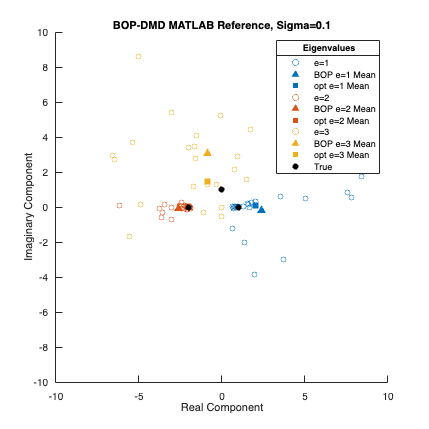

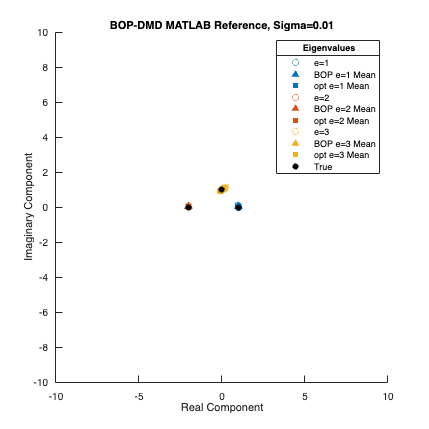

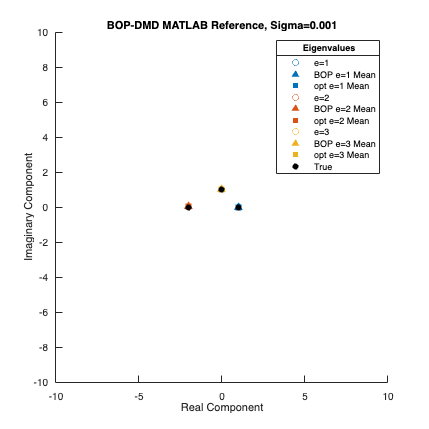


for sigma_ind = 1:length(sigma_array)
    sigma = sigma_array(sigma_ind);
    figure()
    hold on
    for j = [1, 2, 3]
        scatter( ...
            real(mean(lambda_vec_ensembleDMD(j, :, :, sigma_ind), 3)), ...
            imag(mean(lambda_vec_ensembleDMD(j, :, :, sigma_ind), 3)), ...
            25, 'o', "MarkerEdgeColor", colors(j)...
            )
        scatter( ...
            real(mean(lambda_vec_ensembleDMD(j, :, :, sigma_ind), "all")), ...
            imag(mean(lambda_vec_ensembleDMD(j, :, :, sigma_ind), "all")), ...
            50, '^', "MarkerFaceColor", colors(j), "MarkerEdgeColor", colors(j)...
        )
        scatter( ...
            real(mean(lambda_vec_optDMD(j, :, sigma_ind), "all")), ...
            imag(mean(lambda_vec_optDMD(j, :, sigma_ind), "all")), ...
            50, 's', "MarkerFaceColor", colors(j), "MarkerEdgeColor", colors(j)...
        )
    end
    scatter(real(true_eigenvalues),imag(true_eigenvalues),'ko', 'filled')
    xlim(lims)
    ylim(lims)
    title(['BOP-DMD MATLAB Reference, Sigma=', num2str(sigma)])
    xlabel('Real Component')
    ylabel('Imaginary Component')
    lgd = legend('e=1', 'BOP e=1 Mean', 'opt e=1 Mean', 'e=2', 'BOP e=2 Mean', 'opt e=2 Mean', 'e=3', 'BOP e=3 Mean', 'opt e=3 Mean', 'True');
    title(lgd, 'Eigenvalues')
    fig=gcf;
    set(fig, 'Units', 'Inches', 'PaperUnits', 'Inches')
    fig.Position(3:4) = [6, 6];
    fname = ['matlab_reference.BOP-DMD.noise-bug.sigma=', num2str(sigma), '.png'];
    saveas(gcf, fname);
end

And now for the optDMD across each noisy realization

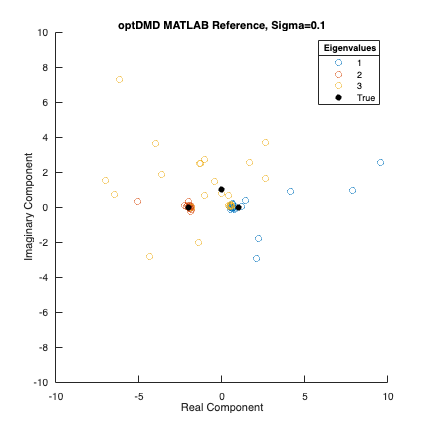

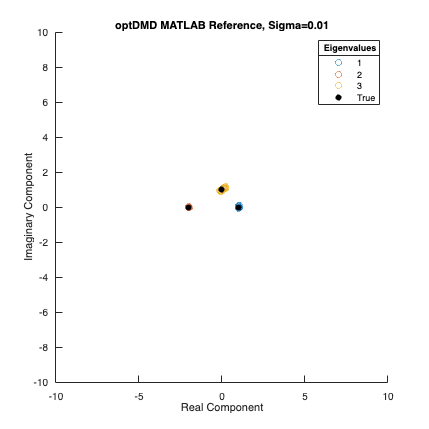

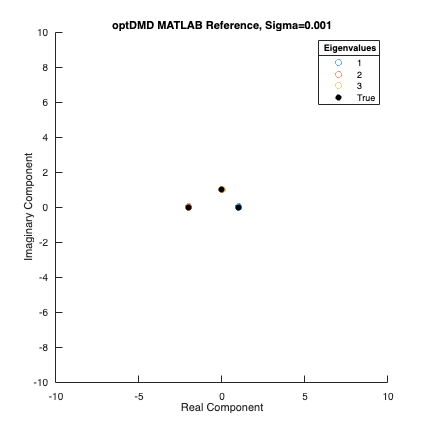

for sigma_ind = 1:length(sigma_array)
    figure()
    hold on
    for j = [1, 2, 3]
        scatter( ...
            real(lambda_vec_optDMD(j, :, sigma_ind)), ...
            imag(lambda_vec_optDMD(j, :, sigma_ind)) ...
            )
    end
    scatter(real(true_eigenvalues),imag(true_eigenvalues),'ko', 'filled')
    xlim(lims)
    ylim(lims)
    title(['optDMD MATLAB Reference, Sigma=', num2str(sigma_array(sigma_ind))])
    xlabel('Real Component')
    ylabel('Imaginary Component')
    lgd = legend('1', '2', '3', 'True');
    title(lgd, 'Eigenvalues')
    fig=gcf;
    set(fig, 'Units', 'Inches', 'PaperUnits', 'Inches')
    fig.Position(3:4) = [6, 6];
end